**Generated clean 439.7562 Hz Signal**:

fs = 44100;  
T = 1;       
t = 0:1/fs:T-1/fs;  % Time vector

f = 439.7562; 
clean_signal = sin(2*pi*f*t);

%sound(clean_signal, fs);


**Recorded Signal**:

[recorded_signal, fs] = audioread('song.mp3');

% stereo to mono
if size(recorded_signal, 2) > 1
    recorded_signal = mean(recorded_signal, 2);
end

% Normalize the recorded signal
recorded_signal = recorded_signal / max(abs(recorded_signal));


From the lecture, the Discrete Fourier Transform (DFT) using FFT is used for frequency analysis. Here we compute the frequency spectrum for the both signals.

% FFT for the clean signal:
Y_clean = fft(clean_signal);
n = length(clean_signal); 
f_clean = (0:n-1)*(fs/n); 
magnitude_clean = abs(Y_clean/n);

% FFT for the recorded signal:
Y_recorded = fft(recorded_signal);
n_rec = length(recorded_signal);
f_recorded = (0:n_rec-1)*(fs/n_rec);
magnitude_recorded = abs(Y_recorded/n_rec);

Finding dominant frequency

% dominant freq in the recorded song:
[~, idx_max] = max(magnitude_recorded(1:floor(n_rec/2)));
dominant_frequency = f_recorded(idx_max);
disp(['Dominant Frequency: ', num2str(dominant_frequency), ' Hz'])

Dominant Frequency: 439.7562 Hz


**Plot Magnitude Spectrums for both:**

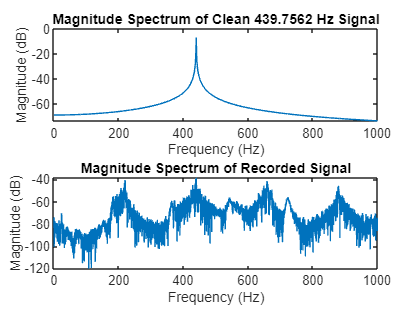

figure;
subplot(2,1,1);
plot(f_clean(1:floor(n/2)), 20*log10(magnitude_clean(1:floor(n/2))));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude Spectrum of Clean 439.7562 Hz Signal');
xlim([0 1000]);  % limit freq. range

subplot(2,1,2);
plot(f_recorded(1:floor(n_rec/2)), 20*log10(magnitude_recorded(1:floor(n_rec/2))));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude Spectrum of Recorded Signal');
xlim([0 1000]);  % limit freq. range

**Smoothing the Recorded Signal **with **Moving Average **

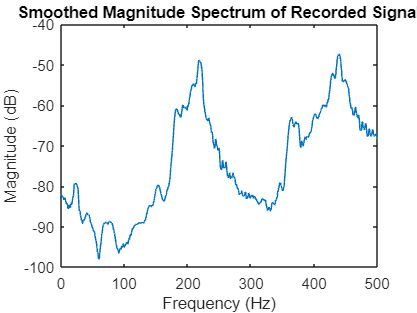

% window size for moving average
windowSize = 50; 
smoothed_magnitude = movmean(magnitude_recorded, windowSize);

% Plot smoothed magnitude
figure;
plot(f_recorded(1:floor(n_rec/2)), 20*log10(smoothed_magnitude(1:floor(n_rec/2))));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Smoothed Magnitude Spectrum of Recorded Signal');
xlim([0 500]);  % lower frequency